# **Intro to MATLAB and Simulink Copilot** 

[⇦ Main Menu](matlab:open('''MainMenu.mlx'''))

In this script, we will explore an introduction to using an AI assistant optimized for MATLAB, Copilot. We will also review Simulink Copilot as well.

[image: Copilot icon]

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View** tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code** using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction

In the [previous script](matlab:open('''.\GenAIFundamentals.mlx''')), we focused on Large Language Models (LLMs) accessed through external APIs and workflows for interacting with them. In many modern softwares, there is now an AI assistants built-in. This can be useful because it can be more familiar with the environment you are working in as compared to other tools that may require some additional connectivity. We will explore how MATLAB and Simulink Copilot works and then use it to help us learn and solve some common engineering problems. The LLM that MATLAB and Simulink Copilot currently uses is the GPT-5 mini model. This model may change as updates come along.

## MATLAB Copilot

MATLAB Copilot provides generative AI-powered capabilities specifically for the MATLAB desktop environment. It has been built to assist in engineering and scientific workflows in MATLAB, and its responses are based on the latest MATLAB documentation. When authoring code, a major time sink can be debugging the code. You can use MATLAB Copilot to learn techniques, develop and test ideas, and improve productivity. It is possible to interact in a variety of ways such as explanations/discussions about topics, modifications to code, generating tests, and completing code.

 **Warning**. To use MATLAB Copilot, it requires MATLAB version **2025a** or later.

### Capabilities

When dealing with AI assistants, it is important to understand the ways in which they work most efficiently for the task. Copilot has three different ways you can interact with it, each way utilizes the same AI assistant. Let's look through each of these options and then we can compare and contrast their application:

  **Pro-tip**. Using **Ctrl+Shift+P** on a **Windows machine** will bring up an "Ask Copilot" window to interact with Copilot within the Live Editor or Command Window. This interaction is available when you select the "Code" button   in the Live Editor Toolstrip.

#### Copilot Chat

Chat is the main way in which you can interact with Copilot. To use it, you can provide a prompt or use one of the example prompts to help you get started. Chat can be opened using the encircled icons in the main MATLAB window (HOME Tab).

 **Warning**. Keep in mind that Copilot Chat does not have any knowledge of code existing in an open [Live Editor file](https://www.mathworks.com/products/matlab/live-editor.html). For code you want to analyze, Chat requires you to explicitly provide code by pasting it into the Chat window.

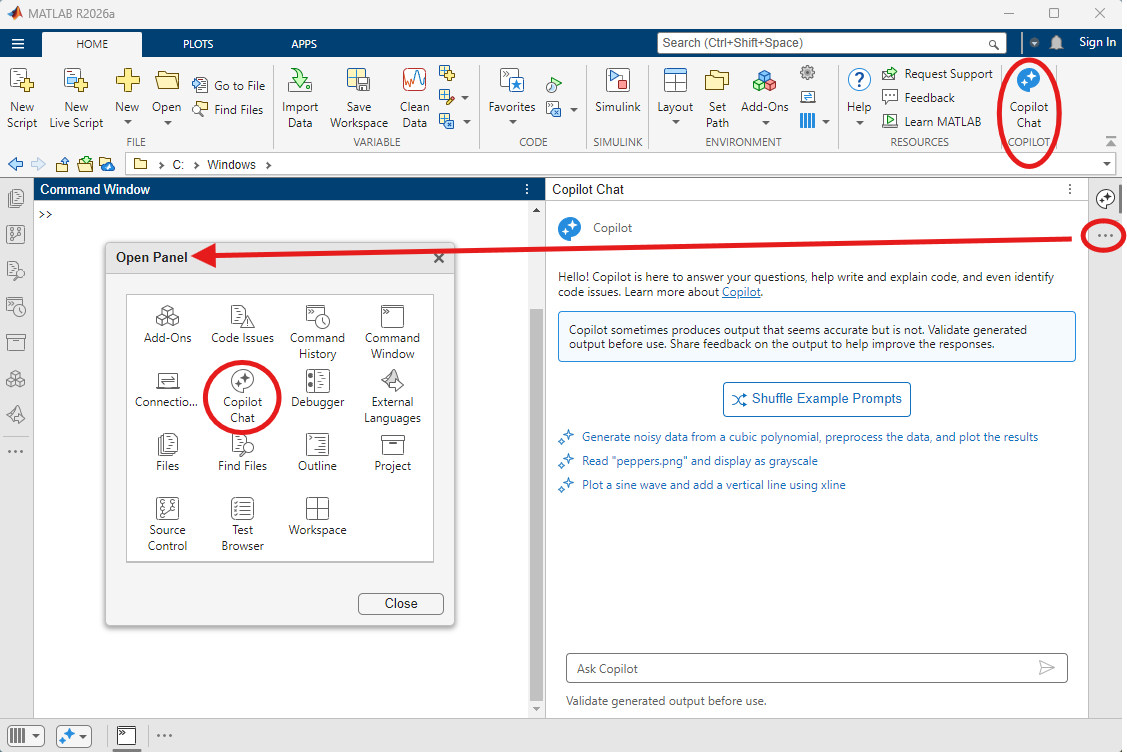 

 **Demonstration**. We will use the following example prompt within MATLAB Copilot Chat to learn more about a topic.

Note that running the same prompt on a different machine will likely produce a different response. Below is an example output from Copilot generated on the machine used to develop this module:

**Nyquist (Nyquist–Shannon) Sampling Theorem — Key Points**

- Statement: A continuous-time signal x(t) that is bandlimited with highest frequency f_max can be perfectly reconstructed from its samples x[n] = x(n / Fs) if the sampling frequency Fs satisfies Fs > 2 f_max.The minimum acceptable rate Fs = 2 f_max is called the Nyquist rate; fN = Fs/2 is the Nyquist frequency.

- Why it matters: Sampling below 2 f_max causes aliasing — high-frequency components fold into lower frequencies and cannot be distinguished or recovered.

- Reconstruction: If the sampling condition holds, ideal reconstruction is done by low-pass filtering the discrete impulses (sinc interpolation). In practice, reconstruction uses interpolation filters or DACs approximating the ideal low-pass.

- Practical considerations

- Real signals are not perfectly bandlimited. Use an anti-aliasing analog low-pass filter before sampling to remove energy above fN.

- Choose some guard band (Fs > 2 f_max) because filters are not ideal — this is oversampling.

- Quantization, noise, and sampling jitter affect practical fidelity but do not change the sampling theorem’s basic requirement.

- For multirate or compressed sensing approaches, different sampling rules can apply (beyond classical Nyquist) when structure or sparsity is exploited.

- Discrete-time frequency folding: Frequencies above fN map (fold) into [0, fN] after sampling. If a sinusoid at f0 > fN is sampled at Fs, its discrete-time observed frequency is |f0 − k Fs| for some integer k that puts it into [0, fN].

**Simple MATLAB Illustration of Aliasing**

**References:**

[What is Nyquist Theorem](https://www.mathworks.com/discovery/nyquist-theorem.html?s_tid=mlcopilot_src1)

**Follow-up Prompts:**

- Can you provide the clearer MATLAB script that plots aliasing in frequency domain?

- How do I design an anti-aliasing filter in MATLAB for a given f_max and transition band?

- Can you show a MATLAB example of anti-aliasing filtering before downsampling?

As you can see, Copilot can provide some background, the context and application, sample code, references, and even follow up prompts to try when learning about new topics. However, AI can give imprecise answers in certain cases. Consider the first statement from the output above:

While this is mostly correct, saying that the minimum acceptable sampling rate is Fs = 2 f_max is confusing because it blurs the line between a theoretical limit and a safe usable condition. In real engineering, this sampling rate would not be considered sufficient because aliasing would still occur. *This leads to why we must verify the AI output before usage*. Feel free to copy and run the example code from above in the Command Window/live script to see what it produces!  

  **Pro-tip**. When you ask Copilot Chat to generate code, there are some helpful features available. You may copy the code to your clipboard, insert the code into Live Editor, or run the code.

 **Warning**. When using the "Insert Code into Editor" feature, ensure the "Code" button   is selected in the Live Editor Toolstrip. Otherwise, it will copy into the Editor as plain text. 

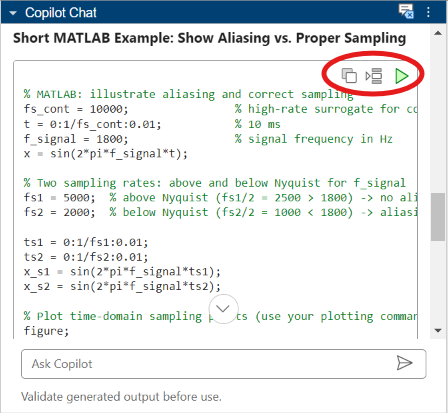

  **Pro-tip**. You can clear your Copilot Chat history and start with a fresh chat when you want to avoid confusion between topics.

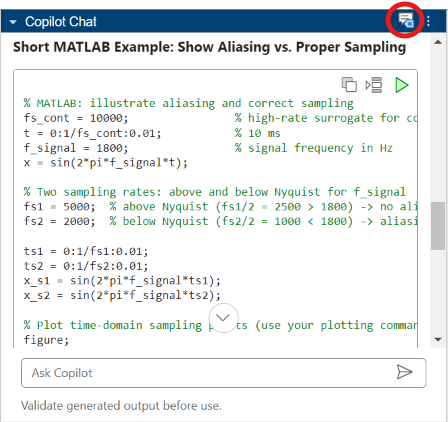

With Copilot, we have answered the "what" regarding the Nyquist Theorem. The next question to answer would be the "why". We will explore the Nyquist Theorem in context in the next section. You will not expected to know the engineering details of the Nyquist Theorem, as Copilot can help you learn more about how it works.

#### Copilot in Editor/Command Window

"Ask Copilot" is a convenient shortcut interface available in the Command Window and Live Editor for interacting with Copilot. "Ask Copilot" can be accessed where you see the encircled sections in the image below.

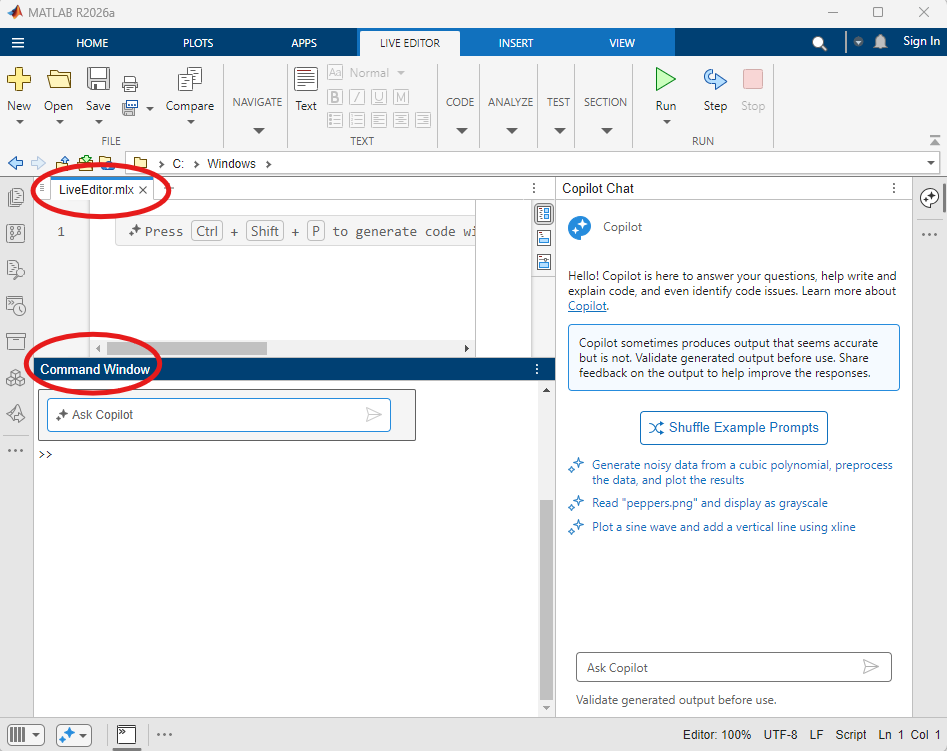

 **Demonstration**. We will use the following example prompt using Ask Copilot to continue the Nyquist theorem example.

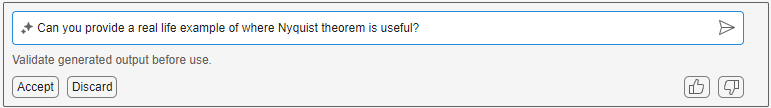

Based on the prompt, Copilot produced code for an example of audio recording of speech. Notice the "Accept" and "Discard" options. It is up to the user of any AI assistant to assess that the generated output makes sense before using it for your personal use. Use AI output only if it fits the task, checks out logically and factually, and is something you’d confidently say is correct after doing your own due diligence. To see the results of the code produced by Copilot, use the following button:

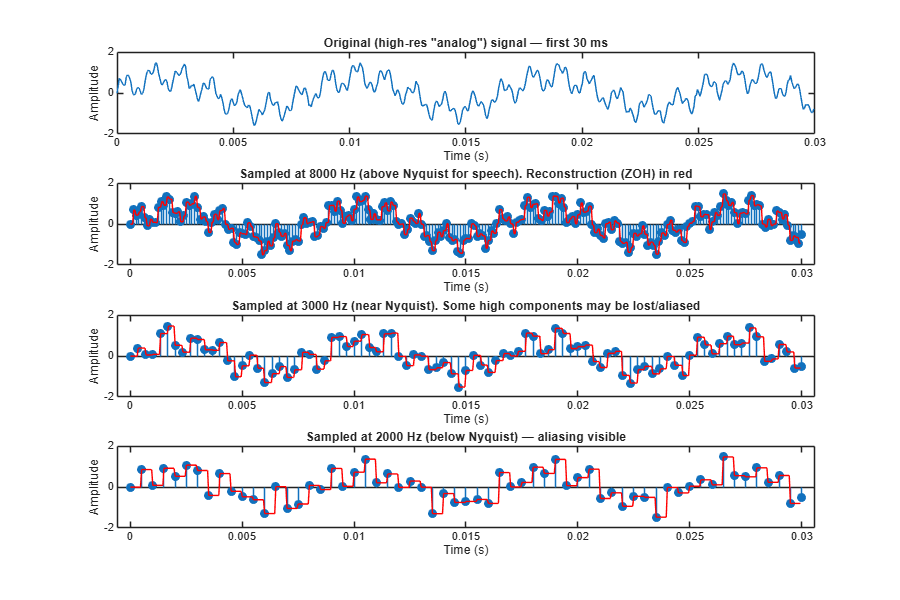

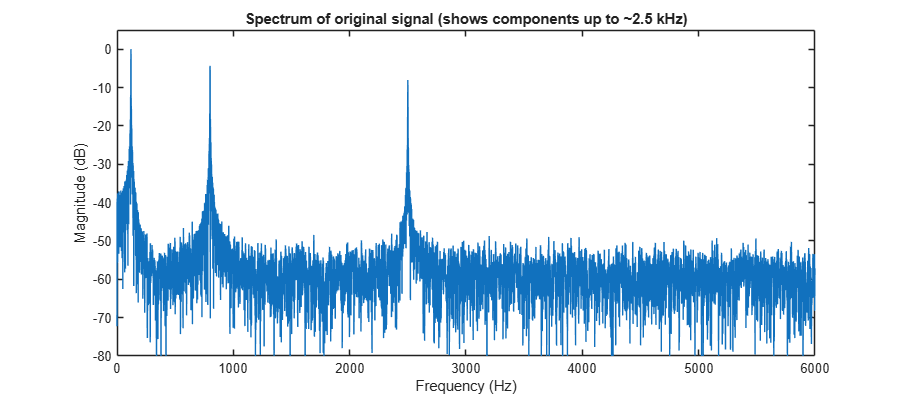

Real-life example: audio recording and playback.
Speech contains energy up to a few kHz (e.g. formants around 800 Hz and 2.5 kHz).
Nyquist theorem says sample rate must be > 2x highest signal frequency to avoid aliasing.
Here: 8 kHz sampling safely preserves components up to 4 kHz; 2 kHz sampling aliases
components above 1 kHz, causing distortion. This is why telephone audio uses 8 kHz
sampling (4 kHz bandwidth) and high-quality audio uses 44.1 kHz or 48 kHz.


 

% Check if project is open. If not, add folders to path.
try
    % Open MATLAB script for audio recording 
    run NyquistCode.mlx;
catch ME
    curloc = matlab.desktop.editor.getActiveFilename;
    rootdir = extractBefore(curloc,filesep+"Scripts");
    addpath(genpath(rootdir));
    run NyquistCode.mlx;
end

  **Pro-tip**. If you wish to review the details of the code produced by Copilot, you can view it [here](matlab:open('''..\Data\NyquistCode.mlx''')). During your review, you may notice the variable `lpFilt` was not used after it was created. This is an example of where AI can generate dead code that is not useful. Always validate the code’s output by using things like AI-generated references or [web searches](https://en.wikipedia.org/wiki/Nyquist%E2%80%93Shannon_sampling_theorem) to sanity-check the results and confirm the AI produced useful code.

We have addressed the "why" for the Nyquist Theorem by applying it to a real life application, where "Ask Copilot" has provided even more detailed code and commentary. Now, you are faced with more complicated code than you previously had and may be unsure with how well it works. Luckily, there are steps that can be taken to help with Copilot. We will close out the Nyquist Theorem example in the next section.

#### Copilot Actions

Copilot Actions provides curated actions with Copilot when dealing with lines of code that you are unfamiliar with. Copilot Actions can be opened using the encircled icons in the Live Editor Toolstrip.

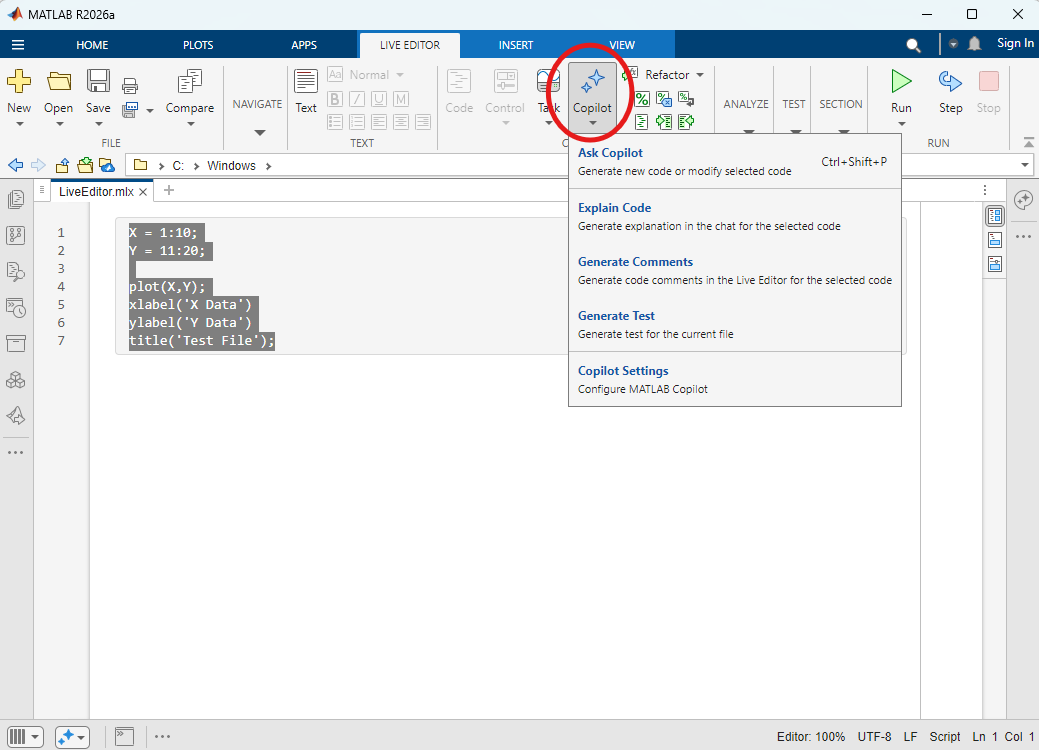

 **Demonstration**. We will use Copilot Actions with the "Explain Code" and "Generate Test" options to complete the Nyquist theorem example.

  **Pro-tip**. When you select "Explain Code", MATLAB will minimize your script and return to Copilot Chat in the main MATLAB window to write out the explanation. *In order for "Explain Code" to work, the code must be selected first.* We can observe a sample of the output produced by "Explain Code" for the [Nyquist code](matlab:open('''..\Data\NyquistCode.mlx''')):

 **Brief Overview:**

          This script simulates a speech-like analog signal, demonstrates sampling at different rates, shows resulting time‑domain reconstructions, and plots the original spectrum to illustrate Nyquist/aliasing effects.

 **Summary:**

          The code builds a high-resolution "analog" waveform composed of a low fundamental and two higher components plus noise, then creates three sampled versions at 8 kHz, 3 kHz, and 2 kHz using simple interpolation to represent sampling. It reconstructs those sampled                         sequences with zero‑order‑hold for plotting, displays short time-domain comparisons, and plots the original spectrum to highlight energy up to ~2.5 kHz. A FIR lowpass filter is designed (but not applied) and a brief explanatory message is printed.

 **Walkthrough:**

- **Create a high-resolution "analog" timebase and speech-like signal:** The code sets a fine sampling rate `fs_analog = 20000` Hz and a 0.5 s time vector `t`. It composes `signal` from three sinusoids (fundamental ~120 Hz, components at 800 Hz and 2500 Hz) and adds small broadband noise to resemble speech. 

- **Define the demonstration sampling rates:** Three sample rates are chosen to illustrate different regimes: `fs_high = 8000` (above Nyquist for the 2.5 kHz component), `fs_low = 3000` (near Nyquist border), and `fs_undersamp = 2000` (below Nyquist for the 2.5 kHz component), so aliasing should appear in the last case.

- **Downsample via interpolation into structured outputs:** An anonymous function `downsample_and_reconstruct` creates a struct with the sampling frequency, sampled time vector, and sampled values obtained by interpolating the high-resolution `signal` at the lower sample instants using linear interpolation. It is applied to each sampling rate to produce `d_high`, `d_low`, and `d_under`.

- **Design a low-pass FIR filter (not applied to reconstructions):** The script calls `designfilt('lowpassfir',...)` to create `lpFilt` with passband 3 kHz and stopband 4 kHz using the high-resolution sample rate `fs_analog`. This produces an idealized reconstruction filter for plotting or conceptual use, though the filter is not actually used later.

- **Reconstruct sampled signals with zero-order-hold for plotting:** Each sampled signal is expanded back onto the high-resolution timebase `t` using `interp1(...,'previous')`, which implements a zero-order-hold (step) reconstruction to visualize how the discrete samples map back into continuous time.

- **Plot short time-domain comparisons:** The first 30 ms (`segIdx`) are plotted in four subplots: the original high-resolution waveform, and three rows showing stems of sample instants with the ZOH reconstruction overlaid in red for 8 kHz, 3 kHz, and 2 kHz sampling. Titles explain expected preservation or aliasing behavior.

- **Plot the original signal spectrum:** An FFT with `nfft = 2^14` computes `X_orig`, and the magnitude (dB, normalized) is plotted from 0–6 kHz to show the spectral components (including the ~2.5 kHz component), supporting the Nyquist discussion.

- **Print an explanatory message to the command window:** A multi-line `fprintf` explains the Nyquist theorem in plain terms, relates the chosen sampling rates to bandwidth and aliasing, and mentions real-world choices like 8 kHz for telephone audio and 44.1/48 kHz for high-quality audio.

"Explain Code" provides an even more thorough walkthrough of the AI-generated code than before to give you the information needed to better understand every step of execution. Now that you have confidence in knowing **how** the code works, it is of equal importance to have confidence that the code **does** actually work. By generating a test, we can ensure the code meets the basic criteria for execution, including expected inputs and outputs. The "Generate Test" function creates a test for the entire script, and we will do this for the Nyquist Theorem code referenced earlier. To review the new test file, use the following button:

 

% Open test file for audio recording
open("TestNyquistCode.m");

Correct! Copilot Actions, specifically the 'explain code' and the 'generate test' actions are the best features to accomplish these tasks.


With an auto-generated test, we can ensure that the code is functional, especially if it is AI-generated. To perform the tests, select the Run Tests   button in the Live Editor toolstrip of the test file. The Test Browser in the main MATLAB window will show whether each test passed or failed:

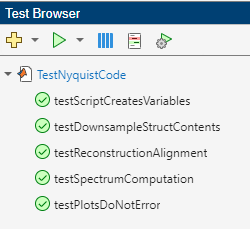

 **Exercise 1.** You are involved in a group project for finding out the optimal amount of solar panels that could fit on a rooftop. To complete your part of the project, it is necessary for a group member to give you code that they created. The group member did not do a good job of providing comments in the code and you are unsure if the code works as written. Which Copilot feature would be best for understanding how this code works and generating tests to verify execution?

ExerciseSol1("Copilot Actions");

D = 0.161837 m, iter = 11, residual = -3.32e-08, converged = 1


### Interacting with MATLAB Copilot

Now that you have some experience working with Copilot, let's try some workflows that support solving other types of technical problems. If you have taken calculus, you have probably used a graphing calculator for solving various equations. Many calculators use the [Newton-Raphson](https://en.wikipedia.org/wiki/Newton%27s_method) technique to solve these equations. Newton-Raphson is an iterative numerical method for finding roots of a differentiable function by taking an initial guess at the solution. It is used because it often converges on a solution much faster than other numerical methods. It has been used to solve problems in physics, engineering, and many other fields.

  **Pro-tip**. Ask Copilot Chat to tell you about the Newton-Raphson method and why it is important to solving engineering problems.

 **Application.** Oil is transferred via pipeline across land masses in many countries. The pipeline must be sized correctly in order to move the oil to its desired destination. Let's solve for the optimal diameter of an oil pipeline based on an algebraic equation that is dependent on pressure and flow rate. This relationship is expressed by the Darcy-Weisbach equation: $\Delta P=f\frac{L}{D}\frac{\rho v^2 }{2}$, where $\Delta P$ is the total pressure loss, $f$ is the friction factor,$L$ is the length of the pipe, $D$ is the diameter of the pipe, $\rho$ is the density of the fluid, and $v$ is the velocity of the fluid.

 **Note**. You will not expected to know the engineering details of the Darcy-Weisbach equation, as Copilot can help you learn more about how it works.

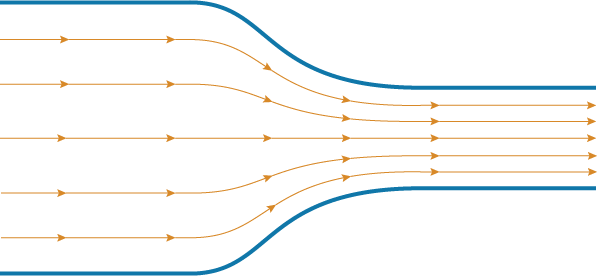

  **Try**. Give Copilot Chat the following prompt and see what it produces: 

 

run DarcyWeisbachCode.mlx;

sumFlag =true;

if sumFlag
    displayFormula("'Based on the output, the problem converged on a solution after 11 iterations with a diameter of 0.162 m. It also mentions a very low residual (or error in the solution) of -3.32e-08.'") %#ok<UNRCH>
else

$$\mathrm{Based on the output, the problem converged on a solution after 11 iterations with a diameter of 0.162 m. It also mentions a very low residual (or error in the solution) of -3.32e-08.}$$

    ...
end

  **Pro-tip**. If you wish to review the details of the Darcy-Weisbach example code produced by Copilot, you can view it [here](matlab:open('''..\Data\DarcyWeisbachCode.mlx''')).

 **Exercise 2.** A baseball is hit high into the air. As it reaches its highest point, it begins to fall back down to earth due to gravity. This problem is described by the **drag force balance equation**: $f\left(v\right)=0=mg-\frac{1}{2}\rho C_d Av^2$, $f\left(v\right)$ is the force balance at terminal velocity, $m$ is the mass of the ball,$g$ is the gravitational constant, $\rho$ is the density of the fluid, $C_d$ is the drag coefficient, $A$ is the area of the ball, and $v$ is the terminal velocity of the ball. Find the terminal velocity of the baseball using the Newton-Raphson method. The mass of the ball is 0.15 kg with a radius of 0.038 m. Use an initial guess of terminal velocity to be 25 m/s. Assume drag coefficient is a function of velocity.

  **Pro-tip**. You can use a similar format of the prompt above for this problem. This exercise will also help you in formulating specific prompts.

 **Note**. Copilot may struggle with this prompt because it requires inferring how the drag coefficient ($C_d$) should be calculated, which can lead to an incorrect solution. Remember that Copilot is powered by an LLM, and LLMs do not always produce correct answers.

ExerciseSol2(33.5);

Correct! You have properly determined the terminal velocity of the baseball as it falls back down to the ground.


 **Reflect**. Can you trust the results that Copilot provided you? How would you go about verifying the output from Copilot?

## Simulink Copilot

Simulink Copilot provides generative AI-powered capabilities into Simulink and Model-Based Design. Powered by the GPT-5 mini model, Simulink Copilot helps you understand Simulink models, diagnose errors, get advice, and automate tasks. This GPT model may change as updates come along.

 **Warning**. To use Simulink Copilot, it requires MATLAB version **2026a** or later. It is also currently unavailable in **MATLAB Online**.

### Capabilities

Simulink Copilot is a recent update to the suite of GenAI capabilities within the MATLAB environment. As of 2026a, Simulink Copilot has a defined set of ways you can interact with it:

You can find the Simulink Copilot interaction in the Simulink Model Toolstrip with the following icon:

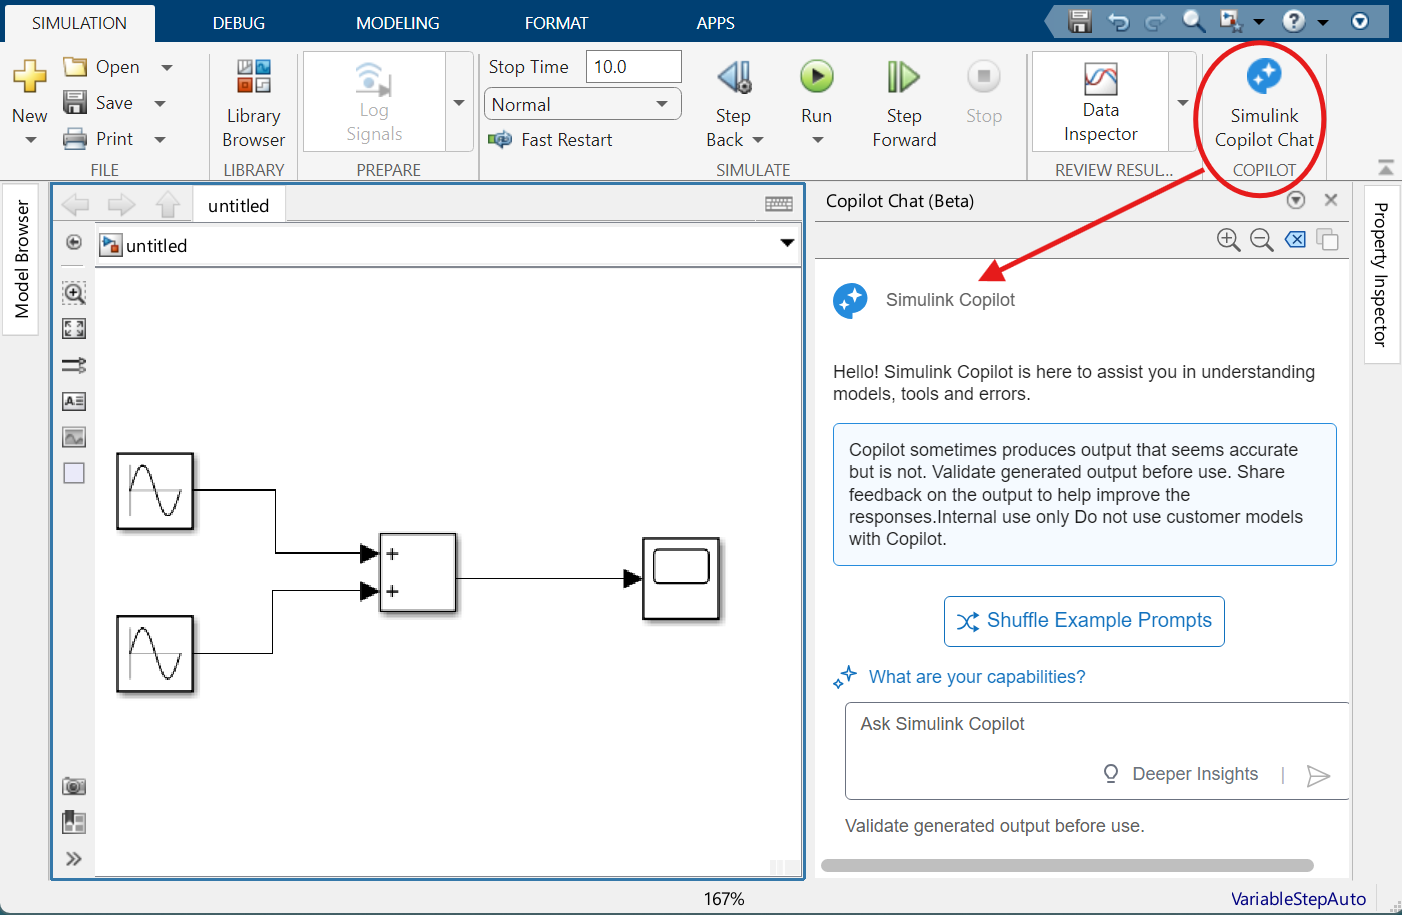

### Interacting with Simulink Copilot

When you provide a prompt to Copilot, it can breakdown the Simulink model into a set of different topics such as:

- High-level purpose

- Core components and roles

- Important block parameter highlights

- Simulation/solver notes

- Typical uses/experiments this model supports

- Warnings and practical checks

- Quick navigation pointers

- Follow-up Prompts

  **Try**. Open the example Simulink model with the button below. Use the following example prompt in **Simulink Copilot** to tell you about the model:

 

% Open sample model
open("SampleModel.slx");

Correct!


 **Exercise 3.** Based on Simulink Copilot's output, what is the most appropriate explanation of this model?

ExerciseSol3("A model for learning how valve position affects tank level, volume, and flow/pressure dynamics.");

## Considerations

When dealing with LLMs, including Copilot, it is important to understand that you may not get the same output every time, even if you ask the same questions repeatedly. Because of this, here are a few ways to not only get closer to the result you want, but also help the LLM learn for future interactions:

- Ask follow up questions

- Copilot is designed to have conversations, so make use of it!

- Verify the output

- Run the resulting code that was generated to see if it provides the output you expect.

- Turn limitations into strengths

- Try the same question again but with different wording if the code generated does not work.

- Use clear context and instructions

- This is the best way to use Copilot. The more specific, the better.

- Clear the chat history

- This will start a fresh chat. This helps when running into **pitfalls**.

A pitfall in the context of LLMs refers to common mistakes or limitations that occur during usage of the tool. Common pitfalls that a user can run into with Copilot (or LLMs in general) are:

- Asking for too much in one prompt

- **Suggestion**: Break up the tasks into smalls steps (piecewise approach)

- Seeing Hallucinations

- **Suggestion**: Verify code suggestions in documentation

- Getting stuck in a conversation (repeated mistakes)

- **Suggestion**: Clear the chat history and start over

## Turn Off Copilot

If your preference is to disable Copilot or adjust the [settings](https://www.mathworks.com/help/matlab-copilot/ug/change-matlab-copilot-settings-window.html) for how you interact with it, you can find those adjustable features using the encircled icon in the main MATLAB window.

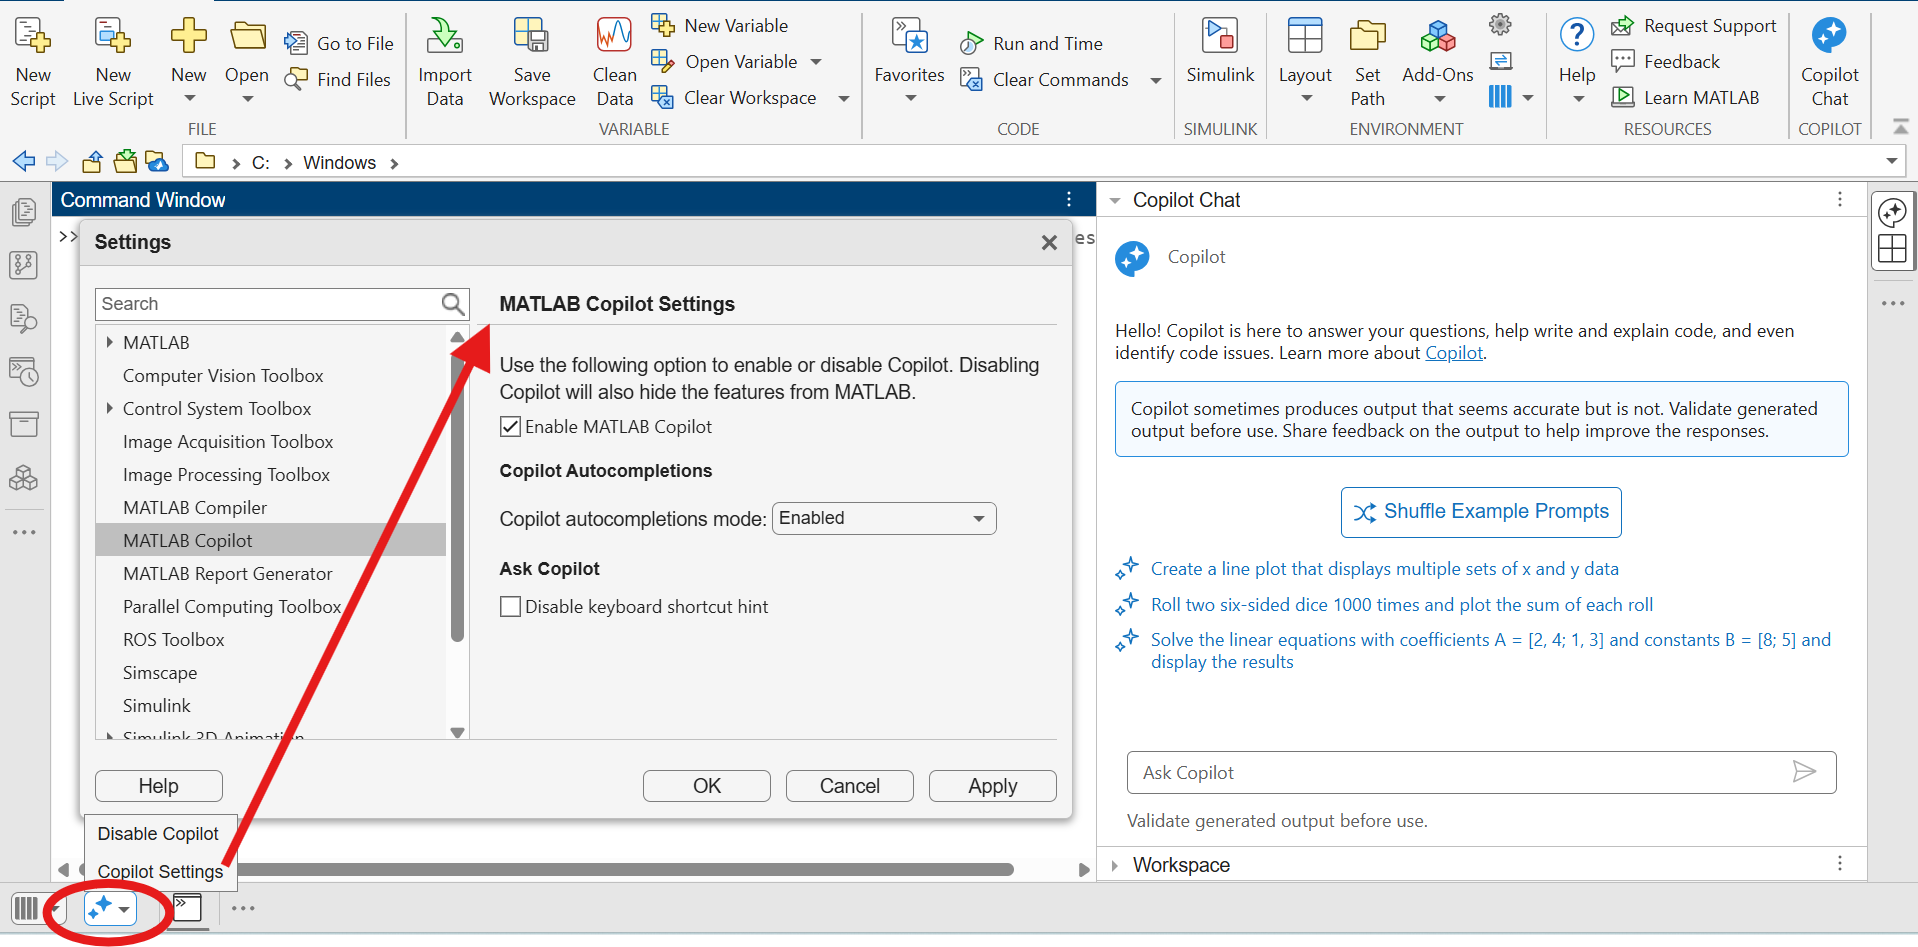

Upon completion of the previous activities, let's clean up our working environment:

 

% Check if project is open. If not, remove folders to path.
if isempty(matlab.project.rootProject) && isempty(which('IntroToCopilot.mlx'))
    ...
else
    curloc = matlab.desktop.editor.getActiveFilename;
    rootdir = extractBefore(curloc,filesep+"Scripts");
    rmpath(genpath(rootdir));
end

## Next Steps

Now you have an understanding of the basics workflows in MATLAB Copilot. If you want to find more prompts for MATLAB Copilot and other skills, visit the [MATLAB on GitHub](https://github.com/matlab) page. In the other scripts, you will learn about the fundamentals of generative AI (including LLMs and tool calling) and using MATLAB Copilot to help solve engineering problems.

## Further Exploration

- [MathWorks Trust Center: Responsible AI Use](https://www.mathworks.com/company/trust-center.html)

- [Coursera: Introduction to MATLAB Copilot](https://www.coursera.org/learn/matlab-copilot)

- [MATLAB Copilot Product Page](https://www.mathworks.com/products/matlab-copilot.html)

- [Simulink Copilot Product Page](https://www.mathworks.com/products/simulink-copilot.html)

- [Your Guide to Agentic AI with MATLAB](https://www.mathworks.com/campaigns/offers/next/agentic-ai-with-matlab.html?s_eid=PSM_1772558841&user_id=6655f889005eb6030c221c8a&sn_type=LINKEDIN&cpost_id=69b2cc3fc82f5631c18ed811&post_id=19761163792&asset_id=ADVOCACY_205_69a95b4818e1532c2ac716ca)

## Glossary

**API** - (Application Programming Interface) A set of rules and protocols that allows different software applications to communicate, exchange data, and share functionality. (↑ Return to Text)

**AI Chatbot/Assistant** - User-facing interface powered by an LLM. (↑ Return to Text)

[⇦ Return to the main menu](matlab:open('''MainMenu.mlx'''))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline** using the icon   at the top right of the Live Editor pane.

function ExerciseSol1(choice)
% Provides feedback for exercise 1
arguments
    choice (1,1) string {mustBeMember(choice,["Select an answer..." "Copilot Chat" "Copilot in Editor/Command Window" "Copilot Actions" "None of the Above"])}
end

if choice == "Select an answer..."
else
    if choice == "Copilot Chat"
        warning("Incorrect. While this could be used, it is not the best feature for this task, especially if you are not familiar with writing prompts. Please try again.");
    elseif choice == "Copilot in Editor/Command Window"
        warning("Incorrect. Similar to Copilot Chat, it is necessary to be familiar with prompting when using this feature. Please try again.");
    elseif choice == "Copilot Actions"
        disp("Correct! Copilot Actions, specifically the 'explain code' and the 'generate test' actions are the best features to accomplish these tasks.");
    elseif choice == "None of the Above"
        warning("Incorrect. There is at least one correct answer. Please try again.");
    end
end
end

function ExerciseSol2(entry)
% Provides feedback for exercise 2
arguments
    entry (1,1) double
end
   entryMargin = 0.5; % Terminal Velocity Tolerance
   if entry >= (33.5 - entryMargin) && entry <= (33.5 + entryMargin) 
    disp("Correct! You have properly determined the terminal velocity of the baseball as it falls back down to the ground.");
   else
    warning("Incorrect. Your answer has exceeded the tolerance of the possible solutions. Please check your prompt or initial conditions and try again.");
   end
end

function ExerciseSol3(choice)
% Provides feedback for exercise 3
arguments
    choice (1,1) string {mustBeMember(choice,["Select an answer..." "A model for learning how valve position affects tank level, volume, and flow/pressure dynamics."...
                                              "A model for learning how sinusoids are created and how they are applied."...
                                              "A model for learning how rapid valve position changes can induce water hammer effects inside of pipes."...
                                              "A model for learning how crude oil reservoirs move oil from one location to another by adjusting valve timing."])}
end

if choice == "Select an answer..."
else
    if choice == "A model for learning how valve position affects tank level, volume, and flow/pressure dynamics."
        disp("Correct!");
    elseif choice == "A model for learning how sinusoids are created and how they are applied."
        warning("Incorrect. Please try again.");
    elseif choice == "A model for learning how rapid valve position changes can induce water hammer effects inside of pipes."
        warning("Incorrect. Please try again.");
    elseif choice == "A model for learning how crude oil reservoirs move oil from one location to another by adjusting valve timing."
        warning("Incorrect. Please try again.");
    end
end
end